receive channel response from white noise input

recObj = audiorecorder;
disp('start receiving.');
recordblocking(recObj, 3);

start receiving.


disp('end receiving');
% h_received = getaudiodata(recObj);

end receiving


plot(h_received);

Estimate impulse response of channel

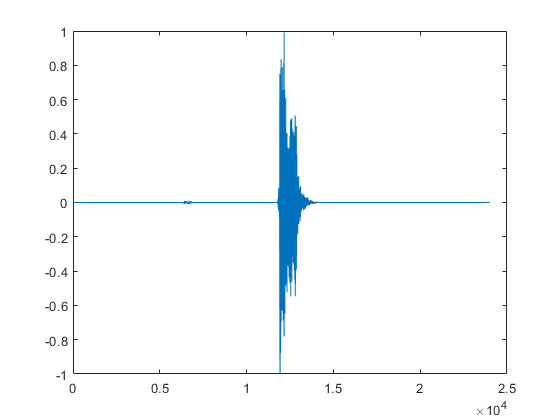

h_xcorr = xcorr(h_received, n);

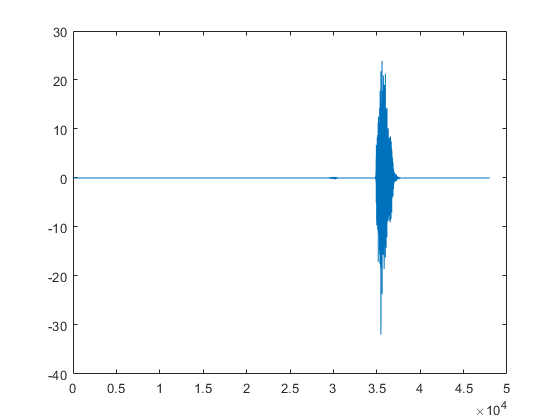

plot(h_xcorr)
for i=1:size(h_xcorr)
    if h_xcorr(i) > 1
        break

    end
end
for j=size(h_xcorr):-1:1
    if h_xcorr(j) > 1
        break
    end
end
h = h_xcorr(i:j)
plot(h)

receive response from encoded text input

recObj = audiorecorder;

h =     1.2131
    1.2010
   -0.0725
    0.3224
   -0.1037
   -1.6572
   -2.5563
   -2.2311
   -0.4965
    1.6319


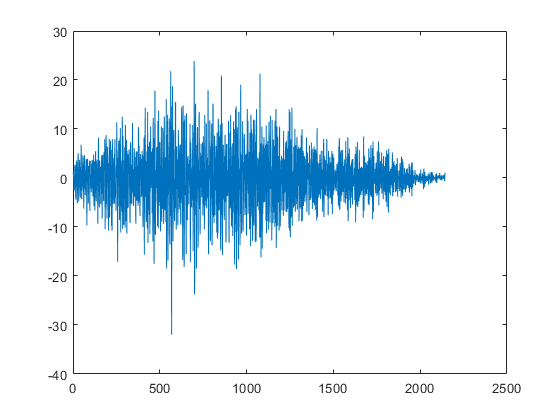

disp('start receiving.');

recordblocking(recObj, 8);
disp('end receiving');
y = getaudiodata(recObj);
plot(y);

start receiving.


n: input white noise

h_received: received response from white noise input

h: estimated channel response

y: received response from encoded text message

Text decoding with digital costas method

% locate received signal
for i=1:size(y)

end receiving


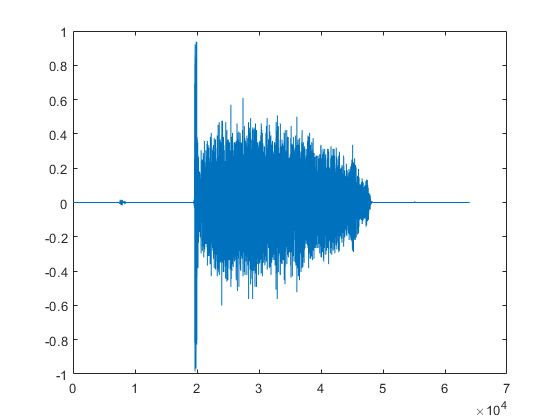

    if y(i) > 0.05
        break

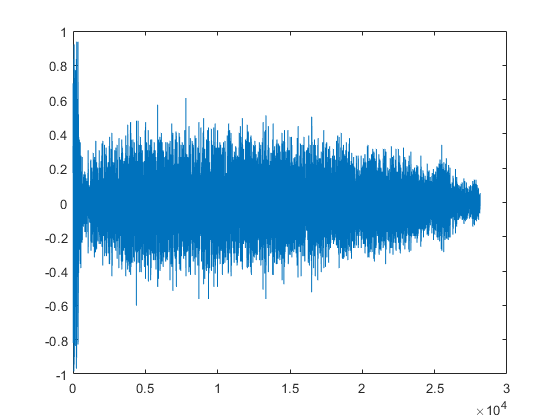

    end
end
for j=size(y):-1:1
    if y(j) > 0.05
        break
    end
end
y_received = y(i:j);
plot(y_received)

% cosine and sine
fc = 2000;
fs = 44100;
time = linspace(0,length(y_received)/fs ,length(y_received));
y_cos = y_received.*cos(2*pi*fc*time.');
y_sin = - y_received.*sin(2*pi*fc*time.')*j;
plot(y_cos)
title('y_cosine')
plot(y_sin)

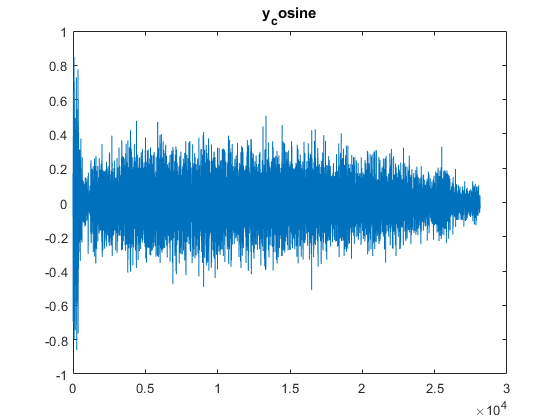

title('y_sine')
y_complex = y_cos + y_sin;
% we are not sure about the parameters for lowpass filter
y_complex = lowpass(y_complex, fc, 44.1e3);
plot(y_complex)

% normalize received signal
y_mag = rms(y_complex);
y_complex = y_complex ./ y_mag;

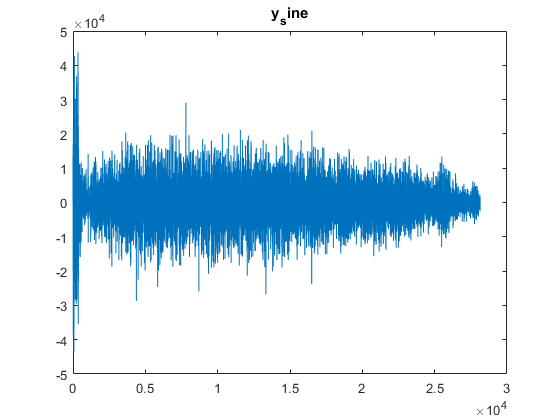

y_size = size(y_complex);


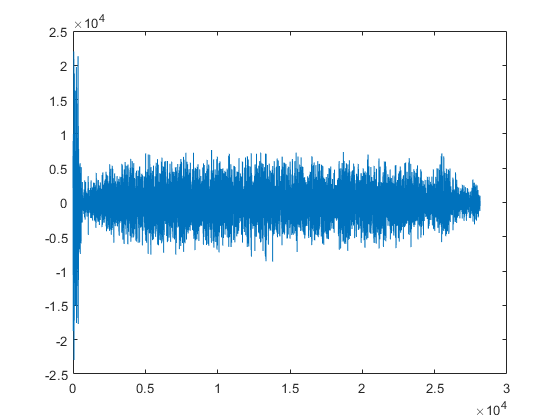

% initialize all variables
phi = zeros(y_size(1),1);
x_prime = zeros(y_size(1),1);
e = zeros(y_size(1), 1);

d = zeros(y_size(1),1);
k = 1;
% unsure of the value for alpha and beta
beta = 0.1;
alpha = 0.01;

% loop through k and minize error
while k < y_size(1)
    x_prime(k) = y_complex(k) * exp(j*phi(k));
    e(k) = -real(x_prime(k)) * imag(x_prime(k));
    d(k) = beta * e(k) + alpha * sum(e(1:k));
    phi(k+1) = phi(k) + d(k);
    while phi(k+1) < -pi
        phi(k+1) = phi(k+1) + 2*pi;
    end
    while phi(k+1) > pi
        phi(k+1) = phi(k+1) - 2*pi;
    end
    k = k + 1;
end
plot(x_prime)

convert bit string to text

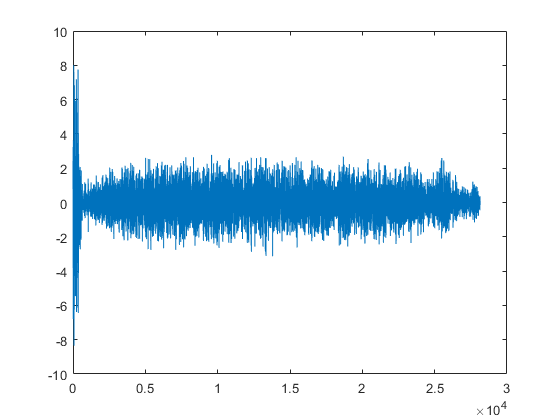

x_res = downsample(x_prime, 20);

% converting to 1 and 0
for i=1:size(x_res)
    if x_res(i) > 0
        x_res(i) = 1;
    end
    if x_res(i) < 0
        x_res(i) = 0;
    end
end

% break down long string into individual character
full_str = sprintf('%d',x_res');
% diff is added here to correct for possible offset
diff = 0;
full_str = full_str(1+diff:1400+diff);
str_size = idivide(int16(strlength(full_str)),int16(7));
ascii_list = strings(str_size, 1);
for i = 0:str_size-1
    ascii_list(i+1) = full_str(i*7+1:(i+1)*7);
end
result = "";
for i = 1:str_size
    result = append(result, char(bin2dec(ascii_list(i))));
end
result

result =     "UUlT+wx6%*"viCypUoCfE[	/W#U+&VVj:td'%fD7f`+HH:V
     [	 x5Je6_U*ro}\D
     XX8]:i8W5
     S_r!7e5(,"xP@V'y)riZsBTjRe_E+cFP%^*kw ``_MkC`]*"{.+N8L%9.U'm;p+dI_ ^8**8|4hjRI5me="
